% load the module data for 120 reps on R = 5, earlyStop = 60
clear; close all;
epochEarlystop = 60;

for i = 1:120
    i
    folderName_R_5_rep_120_diff_data{i} = sprintf('r_5_rep_120_diff_data/%d',i);
    dataFile_R_5_rep_120_diff_data{i} = load(sprintf('data/%s/moduleResult.mat',folderName_R_5_rep_120_diff_data{i}));
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

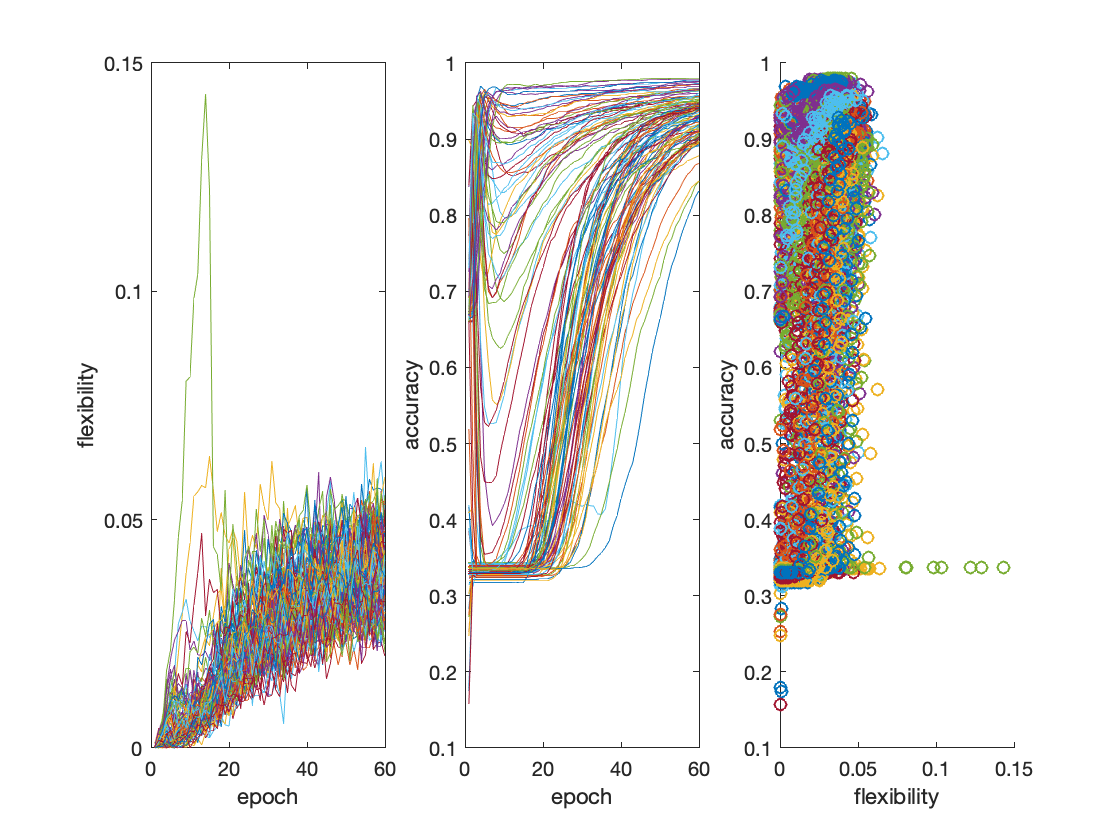

% visualization
figure;
subplot(1,3,1);
for i = 1:120
    plot(dataFile_R_5_rep_120_diff_data{i}.flexibility); hold on;
end
ylabel('flexibility');
xlabel('epoch');
subplot(1,3,2);
for i = 1:120
    plot(dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop)); hold on;
end
ylabel('accuracy');
xlabel('epoch');
subplot(1,3,3);
for i = 1:120
    scatter(dataFile_R_5_rep_120_diff_data{i}.flexibility, dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop)); hold on;
end
ylabel('accuracy');
xlabel('flexibility');

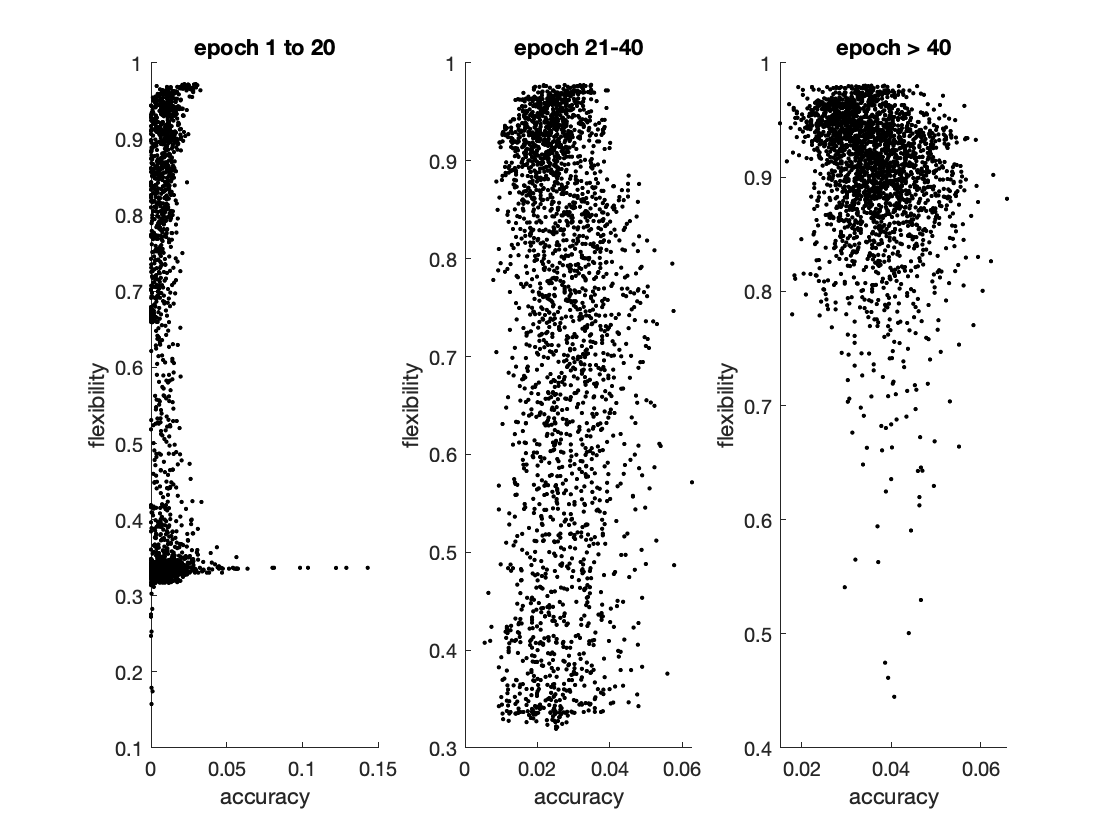

% visualize the relationship between accuracy and flexibility separately
figure;
subplot(1,3,1);
epochStart = 1;
epochEnd = 20;
flex_acc_pair = cell(3,1);
flex_acc_pair{1} = [0,0];
for i = 1:120
    flex_acc_pair{1} = cat(1, flex_acc_pair{1},[dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd),dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd)]);
end
flex_acc_pair{1} = flex_acc_pair{1}(2:end,:);
scatter(flex_acc_pair{1}(:,1), flex_acc_pair{1}(:,2),'black', '.'); hold on;
xlabel('accuracy');
ylabel('flexibility');
title('epoch 1 to 20')
subplot(1,3,2);
epochStart = 21;
epochEnd = 40;
flex_acc_pair{2} = [0,0];
for i = 1:120
    flex_acc_pair{2} = cat(1, flex_acc_pair{2},[dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd),dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd)]);
end
flex_acc_pair{2} = flex_acc_pair{2}(2:end,:);
scatter(flex_acc_pair{2}(:,1), flex_acc_pair{2}(:,2),'black', '.'); hold on;
xlabel('accuracy');
ylabel('flexibility');
title('epoch 21-40')
subplot(1,3,3);
epochStart = 41;
epochEnd = 60;
flex_acc_pair{3} = [0,0];
for i = 1:120
    flex_acc_pair{3} = cat(1, flex_acc_pair{3},[dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd),dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd)]);
end
flex_acc_pair{3} = flex_acc_pair{3}(2:end,:);
scatter(flex_acc_pair{3}(:,1), flex_acc_pair{3}(:,2),'black', '.'); hold on;
xlabel('accuracy');
ylabel('flexibility');
title('epoch > 40')

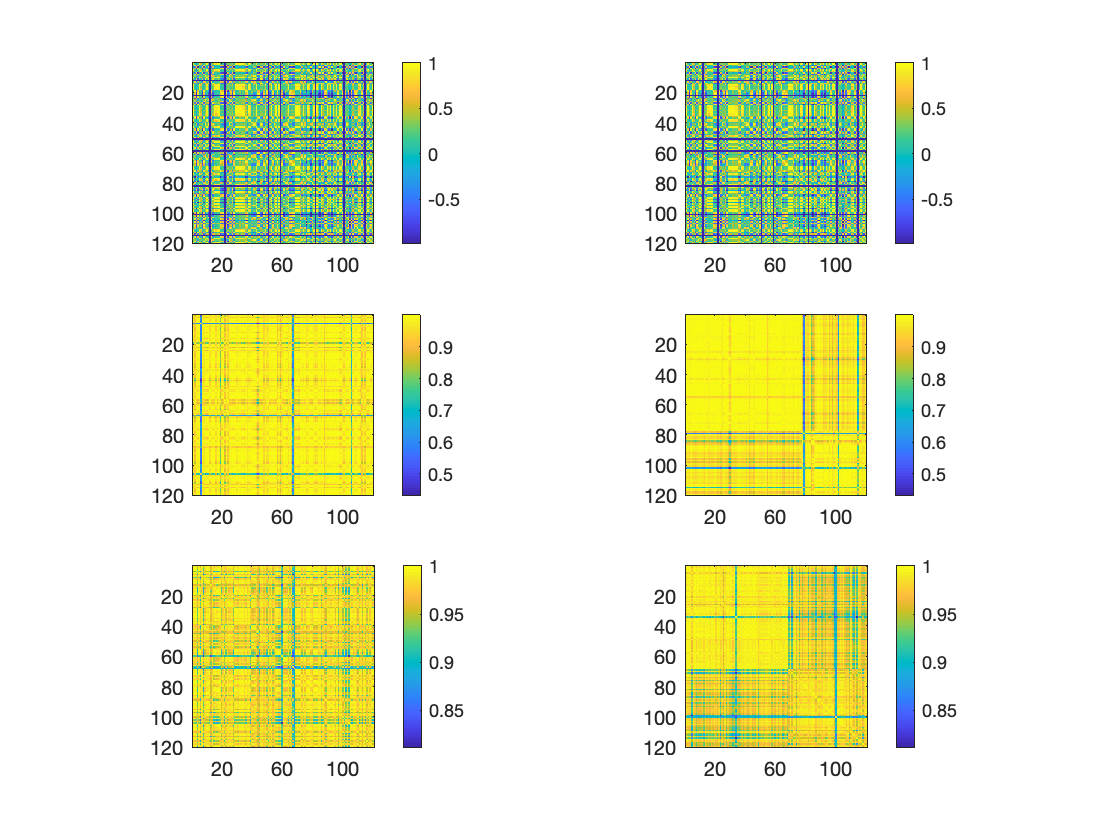

% divide the accuracy curve into three modes
% based on the 1-20, 21-40, 41-60?
accuracySimMatrix = cell(3,1);
for i = 1:120
    for j = 1:120
        accuracySimMatrix{1}(i,j) = corr(dataFile_R_5_rep_120_diff_data{i}.acc(1:20),dataFile_R_5_rep_120_diff_data{j}.acc(1:20));
        accuracySimMatrix{2}(i,j) = corr(dataFile_R_5_rep_120_diff_data{i}.acc(21:40),dataFile_R_5_rep_120_diff_data{j}.acc(21:40));
        accuracySimMatrix{3}(i,j) = corr(dataFile_R_5_rep_120_diff_data{i}.acc(41:end),dataFile_R_5_rep_120_diff_data{j}.acc(41:end));
    end
end
figure;
for i = 1:3
    subplot(3,2,2*i-1)
    imagesc(accuracySimMatrix{i});colorbar; axis square;
    A{1} = accuracySimMatrix{i};
    accCurveType = genRobustCommunityFromASeries(A,1.0,1.0);
    [~,cIdx] = sort(accCurveType);
    subplot(3,2,2*i)
    imagesc(accuracySimMatrix{i}(cIdx, cIdx));colorbar; axis square;
end

% examine the two types of learning curve separately
% plot Type I
load("accuTypeMannual.mat");
epochEarlystop = 60

epochEarlystop = 60

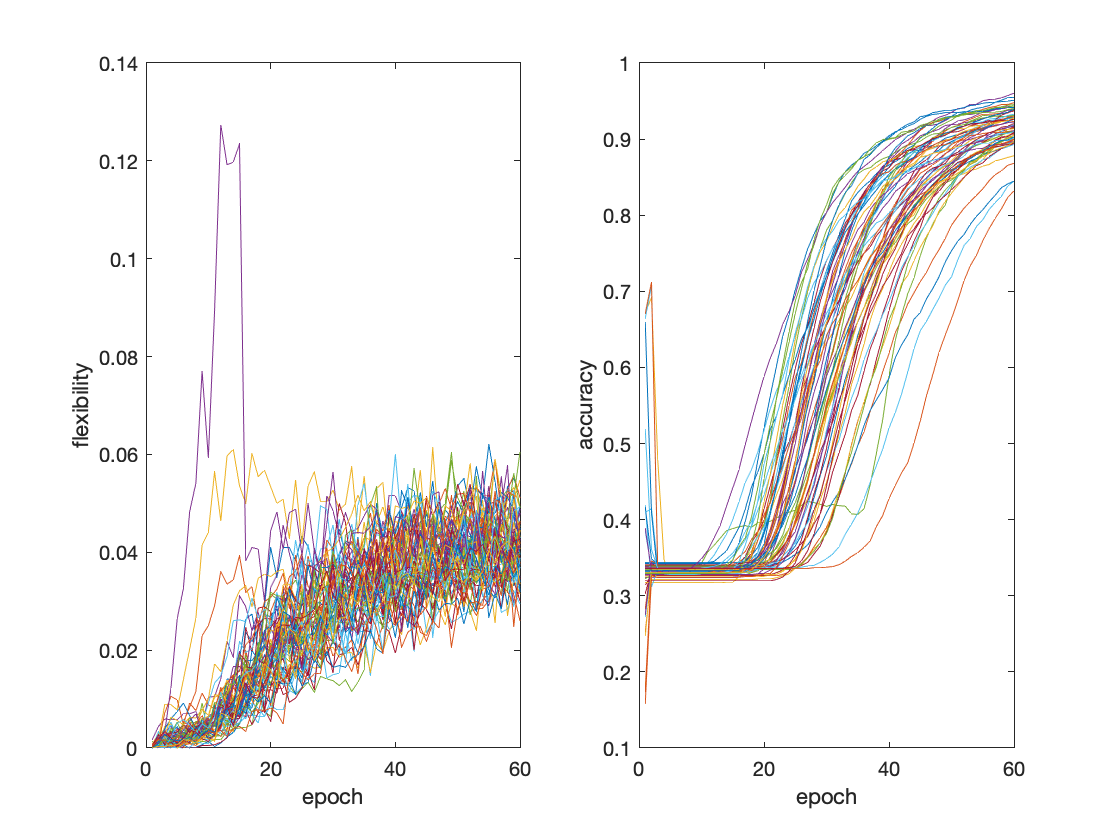

figure;
title('curveType I')
subplot(1,2,1);
type_1_flex_stack = [];
type_1_acc_stack = [];
for i = 1:120
    if accCurveType(i) == 1
        plot(dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop)); hold on;
        type_1_flex_stack = cat(2,type_1_flex_stack, dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop));
    end
end
ylabel('flexibility');
xlabel('epoch');
subplot(1,2,2);
for i = 1:120
    if accCurveType(i) == 1
        plot(dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop)); hold on;
        type_1_acc_stack = cat(2, type_1_acc_stack, dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop));
    end
end
ylabel('accuracy');
xlabel('epoch');

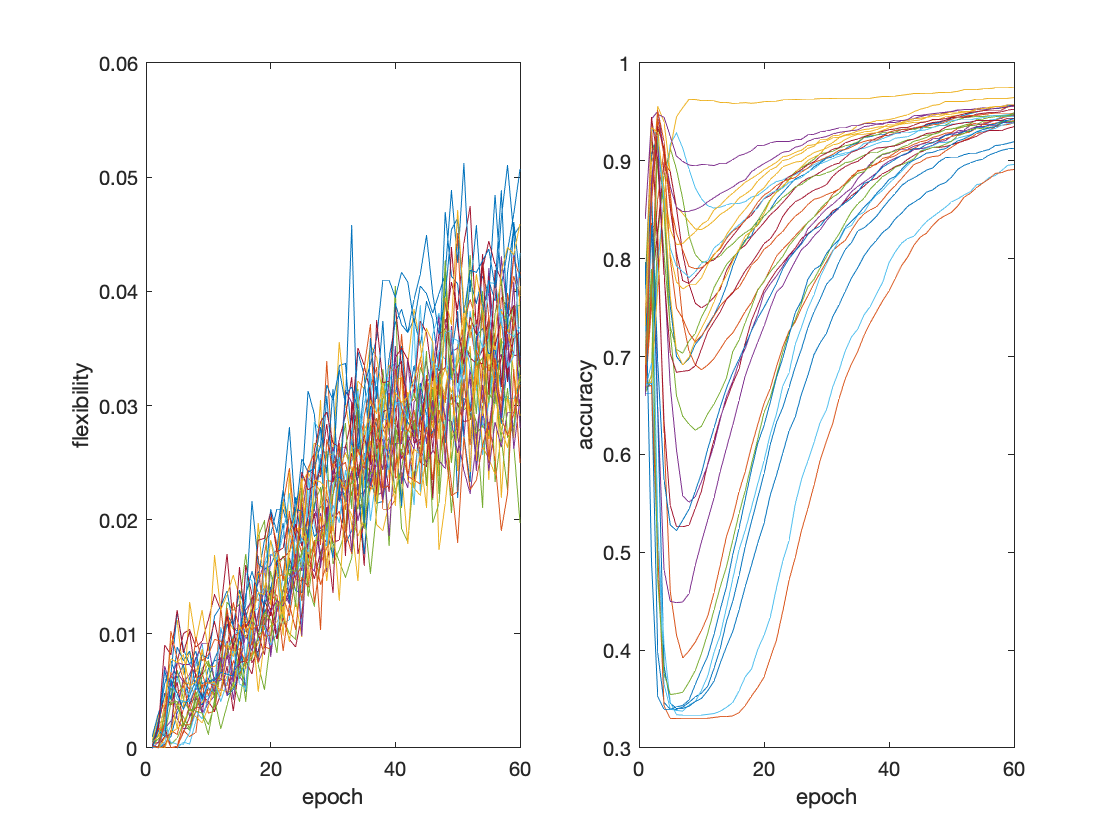



% plot Type II
figure;
type_2_flex_stack = [];
type_2_acc_stack = [];
title('curveType II')
subplot(1,2,1);
for i = 1:120
    if accCurveType(i) == 2
        plot(dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop)); hold on;
        type_2_flex_stack = cat(2,type_2_flex_stack, dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop));
    end
end
ylabel('flexibility');
xlabel('epoch');
subplot(1,2,2);
for i = 1:120
    if accCurveType(i) == 2
        plot(dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop)); hold on;
        type_2_acc_stack = cat(2, type_2_acc_stack, dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop));
    end
end
ylabel('accuracy');
xlabel('epoch');

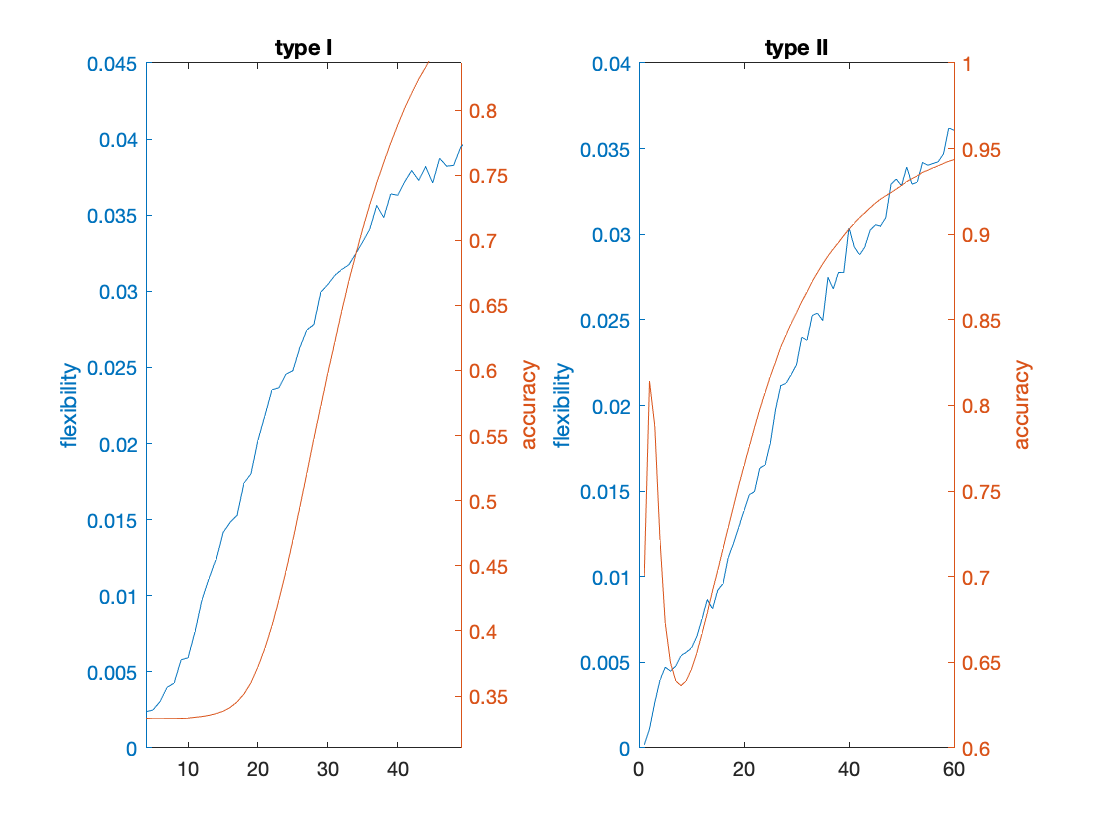


figure;
subplot(1,2,1)
yyaxis left;
plot(mean(type_1_flex_stack'));
ylabel('flexibility')
yyaxis right;
plot(mean(type_1_acc_stack'));
ylabel('accuracy')
title('type I');
subplot(1,2,2)
yyaxis left;
plot(mean(type_2_flex_stack'));
ylabel('flexibility')
yyaxis right;
plot(mean(type_2_acc_stack'));
ylabel('accuracy')
title('type II');

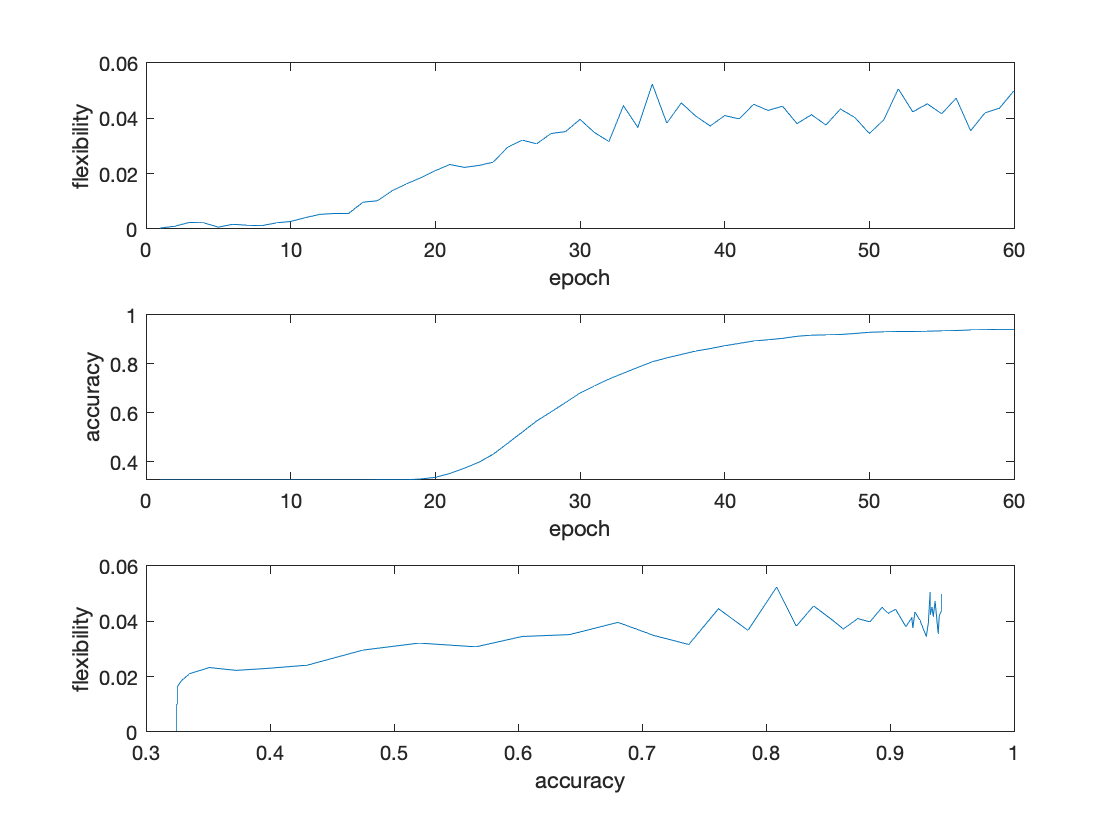

% view separately
figure;
title('curveType I')
idx = 31;
subplot(3,1,1);
plot(dataFile_R_5_rep_120_diff_data{idx}.flexibility);
ylabel('flexibility');
xlabel('epoch');
subplot(3,1,2);
plot(dataFile_R_5_rep_120_diff_data{idx}.acc(1:epochEarlystop));
ylabel('accuracy');
xlabel('epoch');
subplot(3,1,3)
plot(dataFile_R_5_rep_120_diff_data{idx}.acc(1:epochEarlystop),dataFile_R_5_rep_120_diff_data{idx}.flexibility(1:epochEarlystop));
ylabel('flexibility');
xlabel('accuracy');

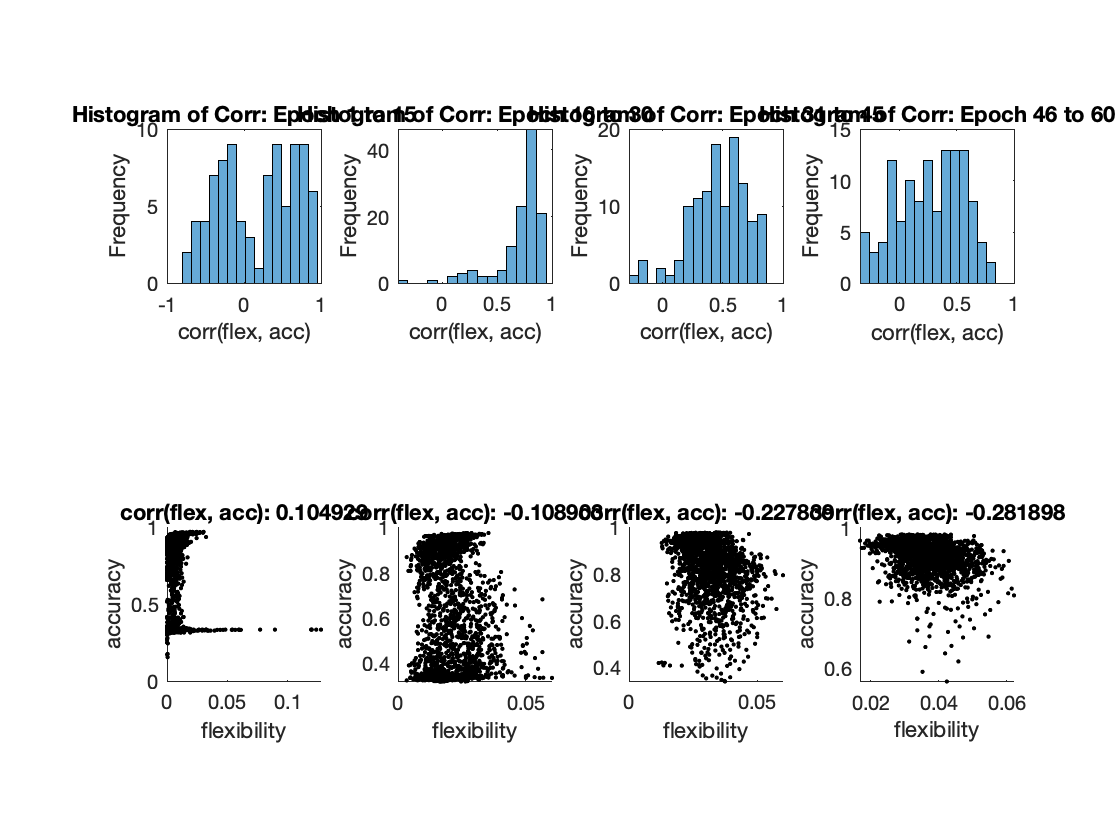

% visualize the degree distribution for individual difference and within subjects
% visualize the relationship between accuracy and flexibility separately
flex_acc_pair = cell(4,1);
flex_acc_corr = zeros(120,4);
epochDiff = 60/length(flex_acc_pair);
for k = 1:length(flex_acc_pair)
    flex_acc_pair{k} = [0,0];
    epochStart = 1 + epochDiff*(k-1);
    epochEnd= epochDiff*k;
    for i = 1:120
        flex_acc_pair{k} = cat(1, flex_acc_pair{k},[dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd),dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd)]);
        flex_acc_corr(i,k) = corr(dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd), dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd));
    end
    flex_acc_pair{k} = flex_acc_pair{k}(2:end,:);
end
figure;
for i = 1:4
    subplot(2,4,i);
    histogram(flex_acc_corr(:,i),15);
    axis square;
    title(sprintf('Histogram of Corr: Epoch %d to %d', 1 + epochDiff*(i-1), epochDiff*i));
    xlabel('corr(flex, acc)');
    ylabel('Frequency');
end
for i = 1:4
    subplot(2,4,i+4);
    scatter(flex_acc_pair{i}(:,1), flex_acc_pair{i}(:,2),'black', '.'); hold on;
    axis square;
    title(sprintf('corr(flex, acc): %f', corr(flex_acc_pair{i}(:,1), flex_acc_pair{i}(:,2))));
    xlabel('flexibility');
    ylabel('accuracy');
end